syms t real;
syms theta1(t) theta2(t);
syms tau;
syms I1x I1y I1z l1 m1 d1 real;
syms I2x I2y I2z l2 m2 d2 real;
syms g real;
syms ang real;
assumeAlso(theta1(t),'real');
assumeAlso(theta2(t),'real');

global K_gain;
global K_gain_fb;
global I_fn h_fn del_fn gam_fn;
global Tau_t;

g_f = [0;0;-g];

Id = eye(3);
Id_1 = eye(6);
ZO = zeros(3,3);
ZO_1 = zeros(6,6);
ZO_c = zeros(6,1);
ZO_c2 = zeros(3,1);

Rz = [cos(ang),-sin(ang),0;sin(ang),cos(ang),0;0,0,1];
Ry = [cos(ang),0,sin(ang);0,1,0;-sin(ang),0,cos(ang)];

T2_1 = subs(Rz,ang,theta1);
T3_1 = T2_1*subs(Ry,ang,pi/2);
T4_1 = T3_1*subs(Rz,ang,theta2);


I1c = [I1x,0,0;0,I1y,0;0,0,I1z];
I2c = [I2x,0,0;0,I2y,0;0,0,I2z];

I1 = I1c + ((m1*d1*d1)*Id) - (m1*([d1,0,0]'*[d1,0,0]));
I2 = I2c + ((m2*d2*d2)*Id) - (m2*([d2,0,0]'*[d2,0,0]));
d_1 = T2_1*[d1,0,0]';
d_2 = T4_1*[d2,0,0]';

e1 = [0,0,1]';
e2 = [0,0,1]';
p1 = [e1;ZO_c2];
%p1 = [e1;cross(e1,d_1)];
p2 = [T3_1*e2;ZO_c2];
%p2 = [T3_1*e2;cross(T3_1*e2,d_2)];
a2_1 = T2_1*[-l1,0,0]';
a3_2 = T4_1*[-l2,0,0]';
A21 = [Id ZO;vec_cross(a2_1) Id];
Nl = [Id_1,ZO_1;A21,Id_1];
Nd = [p1,ZO_c;ZO_c,p2];
I1_f = T2_1*I1*(T2_1');
I2_f = T4_1*I2*(T4_1');
M1 = [I1_f,m1*vec_cross(d_1);-m1*vec_cross(d_1),m1*Id];
M2 = [I2_f,m2*vec_cross(d_2);-m2*vec_cross(d_2),m2*Id];
M = [M1,ZO_1;ZO_1,M2];
ang1 = formula(diff([0;0;theta1],t));
ang2 = ang1 + (T4_1*formula(diff([0;0;theta2],t)));
%ang2 = (T3_1*formula(diff([0;0;theta2],t)));
w1 = [vec_cross(ang1),ZO;ZO,vec_cross(ang1)];
w2 = [vec_cross(ang2),ZO;ZO,vec_cross(ang2)];
W = [w1,ZO_1;ZO_1,w2];
E1 = [Id,ZO;ZO,ZO];
E = [E1,ZO_1;ZO_1,E1];
N = Nl*Nd;
N_d = diff(N,t);
joint_r = [diff(theta1,t);diff(theta2,t)];
twist = N*joint_r;
twist_d = diff(twist,t);

%Wrench
W1_e = [cross(d_1,m1*g_f);m1*g_f];
W2_e = [cross(d_2,m2*g_f);m2*g_f];
Wrench = [W1_e;W2_e];
ext_f = [tau;0];

eq = ((M*twist_d) + (W*M*E*twist) - Wrench);
f_eq = simplify(N'*eq);

I = simplify(N'*M*N);
% (N'*N_d*joint_r)
% (N'*W*M*E*twist)
% (N'*Wrench)
h = simplify((N'*M*N_d*joint_r) + (N'*W*M*E*twist) - (N'*Wrench));

%Just checking with other equation
% test = [d1,d2,g];test_val = [l1/2,l2/2,0];
% vpa(subs(I,test,test_val))
% vpa(subs(h,test,test_val))

% Theta double dot
%simplify(I\(ext_f - h));
I_1 = [I1x I1y I1z l1 m1 d1];
I_2 = [I2x I2y I2z l2 m2 d2];
I = (subs(I,I_1,[1 1 1 1 1 0.5]));
I = (subs(I,I_2,[1 1 1 1 1 0.5]));
h = (subs(h,I_1,[1 1 1 1 1 0.5]));
h = (subs(h,I_2,[1 1 1 1 1 0.5]));
I = (subs(I,g,9.81));
h = (subs(h,g,9.81));
theta_d_d = formula(vpa(simplify(I\(ext_f - h))));

q_d_d = diff(joint_r,t);
vpa(simplify((I*q_d_d)+(h)-(ext_f)));


%State space representation

syms y1 y2 y3 y4 real;
% y1 = theta1
% y2 = diff(theta1,t)
% y3 = theta2 - pi
% y4 = diff(theta2,t)

y1_d = y2;
y2_d = subs(theta_d_d(1),[diff(theta1,t),diff(theta2,t)],[y2,y4]);
y2_d = subs(y2_d,[theta1,theta2],[y1,y3+pi]);
y3_d = y4;
y4_d = subs(theta_d_d(2),[diff(theta1,t),diff(theta2,t)],[y2,y4]);
y4_d = subs(y4_d,[theta1,theta2],[y1,y3+pi]);

y = [y1;y2;y3;y4];
yd_d = [y1_d;y2_d;y3_d;y4_d];

%Non linear affine system : Y_dot = F(Y) + tau*G(Y)
g_s = diff(yd_d,tau);
f_s = simplify(yd_d - (tau*g_s));

global static_force;
static_force = 0;

%Linearinzing about (y,u) at (0,0)
digits(5);
A_y = [diff(yd_d,y1),diff(yd_d,y2),diff(yd_d,y3),diff(yd_d,y4)];
A = simplify(subs(A_y,[y1,y2,y3,y4,tau],[0,0,0,0,0]));
B_y = diff(yd_d,tau);
B = simplify(subs(B_y,[y1,y2,y3,y4,tau],[0,0,0,0,0]));
poles = [-0.5,-3,-3,-1];
%K_gain = double(Ackermann(A,B,poles));

%LQR Cost

Q = [0.1,0,0,0;0,10000,0,0;0,0,10000,0;0,0,0,1];
R = 100000;
[K_gain,S,lqrpoles] = lqr(double(A),double(B),Q,R);


%Feedback lineariztion
syms v;

z1 = y3;
z2 = y4;
eta1 = y1;
eta2 = (y2*cos(y3))-(2.5*y4);
norm_diff = jacobian([z1;z2;eta1;eta2],y)*yd_d;
gama_y = simplify(diff(norm_diff(2),tau));
delta_y = simplify(norm_diff(2) - (tau*gama_y));
A_fb = [0,1;0,0]; B_fb = [0;1];
Q_fb = [10000,0;0,10000]; R_fb = 100000;
[K_gain_fb,S_fb,lqrpoles_fb] = lqr(double(A_fb),double(B_fb),Q_fb,R_fb);
poles_fb = [-1,-1];
%K_gain_fb = Ackermann(A_fb,B_fb,poles_fb);
K_gain_fb = [K_gain_fb(1),K_gain_fb(2),0,0];



%Creating Function handlers

states = [y1,y2,y3,y4];

I_y = subs(I,[theta1,theta2],[y1,y3+pi]);
h_y = subs(h,transpose(joint_r),[y2,y4]);
h_y = subs(h_y,[theta1,theta2],[y1,y3+pi]);

I_fn = matlabFunction(I_y,"Vars",{states},"Optimize",false);
h_fn = matlabFunction(h_y,"Vars",{t,states},"Optimize",false);

del_fn = matlabFunction(delta_y,"Vars",{states},"Optimize",false);
gam_fn = matlabFunction(gama_y,"Vars",{states},"Optimize",false);

T2_1_y = subs(T2_1,[theta1,theta2],[y1,y3+pi]);
T2_1_fn = matlabFunction(T2_1_y,"Vars",{states},"Optimize",false);

T4_1_y = subs(T4_1,[theta1,theta2],[y1,y3+pi]);
T4_1_fn = matlabFunction(T4_1_y,"Vars",{states},"Optimize",false);


%Using Feedback linearization

%Using all the information to derive equations using ODE-45
tic

tstart = 0;
tend = 10;
dt = 0.01;
n = size(tstart:dt:tend-dt,2) + 1;

q = [theta1;theta2];
q_dot = joint_r;

%% states = [x(1);x(3);x(2)-pi;x(4)]; %Remember this
xinit = [0 3 0 0 0]; %Angles ; Rates ; integral of theta2
states_y = [xinit(1);xinit(3);xinit(2)-pi;xinit(4)];
Tau_t = [0,0];
X_final = zeros(n,5);
X_ode = zeros(n,5);
tspan2 = zeros(n,1);

X_final(1,:) = xinit;
tspan2(1,:) = zeros(1,1);
X_ode(1,:) = xinit;
iter = 2;
opts = odeset('AbsTol',1e-4);
for ti = tstart:dt:tend-dt

    tspan = [ti ti+dt];
    %[time,x_ode] = ode45(@(time,x_ode)Spatial2RintegratingFBL(time,x_ode,(I_ode),(h_ode),del_y,gam_y), tspan, xinit);
    [time,x_ode] = ode45(@(time,x_ode)Spatial2RintegratingFBL(time,x_ode), tspan, xinit,opts);
    xinit = x_ode(size(x_ode,1),:);

%     xinit(1) = rem(xinit(1),(2*pi));
%     xinit(2) = rem(xinit(2),(2*pi));

    states_y = [xinit(1);xinit(3);xinit(2)-pi;xinit(4)];
    
    X_final(iter,:) = xinit(size(xinit,1),:);
    tspan2(iter,:) = ti + dt;
    %x_ode(size(x_ode,1),:) = xinit; %%Chumma trying
    X_ode(iter,:) = x_ode(size(x_ode,1),:);
    iter = iter + 1;
end
toc

Elapsed time is 4.052401 seconds.


tic
tstart2 = 0;
tend2 = 10;
dt2 = 0.01;
tspan2 = tstart2:dt2:tend2;
xinit2 = [0 3 0 0 0];
opts2 = odeset('AbsTol',1e-5);
[time2,x_ode2] = ode45(@(time2,x_ode2)Spatial2RintegratingFBL(time2,x_ode2),tspan2, xinit2,opts2);
toc

Elapsed time is 0.089979 seconds.



%plot(time2,(180/pi)*x_ode2(:,2))

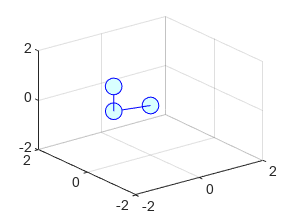

%Animation

%%

clc
close all


States_final = [X_final(:,1),X_final(:,3),X_final(:,2)-pi,X_final(:,4)];
l1_v = 1;
l2_v = 1;

pt1 = T2_1_fn(States_final(1,:))*[l1_v,0,0]';
pt2 = pt1 + (T4_1_fn(States_final(1,:)))*[l2_v,0,0]';

X = [0 pt1(1) pt2(1)];
Y = [0 pt1(2) pt2(2)];
Z = [0 pt1(3) pt2(3)];

filename = 'animation_ts.gif';
p = plot3(X, Y,Z,'-o','Color','b','MarkerSize',10,...
    'MarkerFaceColor','#D9FFFF');
PT1 = zeros(length(tspan2),3);
PT2 = zeros(length(tspan2),3);

for n = 2:length(tspan2)

pt1 = T2_1_fn(States_final(n,:))*[l1_v,0,0]';
pt2 = pt1 + (T4_1_fn(States_final(n,:)))*[l2_v,0,0]';
PT1(n-1,:) = pt1';
PT2(n-1,:) = pt2';

X = [0 pt1(1) pt2(1)];
Y = [0 pt1(2) pt2(2)];
Z = [0 pt1(3) pt2(3)];
xlim([-2, 2]); 
ylim([-2, 2]); 
zlim([-2, 2]);
 set(p, 'YData', Y , 'Xdata',X, 'Zdata',Z)
 grid on;

 %set(p2,'YData',[0 pt3(2)],'Xdata',[0 pt3(1)]);
 pause(0.001); 

     % Saving the figure
    frame = getframe(gcf);
    im = frame2im(frame);
    [imind,cm] = rgb2ind(im,256);
    if n == 2
        imwrite(imind,cm,filename,'gif', 'Loopcount',inf,...
        'DelayTime',0.025);
    else
        imwrite(imind,cm,filename,'gif','WriteMode','append',...
        'DelayTime',0.025);
    end

end 

%delete(f);


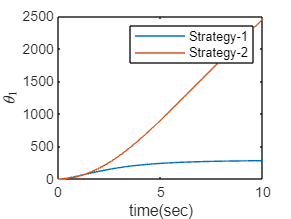

%plot(tspan2,(180/pi)*X_final(:,1))
plot(tspan2,(180/pi)*X_final(:,1),time2,(180/pi)*x_ode2(:,1))
ylabel('$\theta_1$', 'Interpreter', 'latex');
xlabel("time(sec)")
legend(["Strategy-1","Strategy-2"])

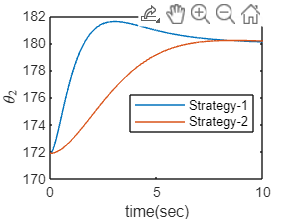

%plot(tspan2,(180/pi)*X_final(:,2))
plot(tspan2,(180/pi)*X_final(:,2),time2,(180/pi)*x_ode2(:,2))
ylabel('$\theta_2$', 'Interpreter', 'latex');
xlabel("time(sec)")
legend(["Strategy-1","Strategy-2"])

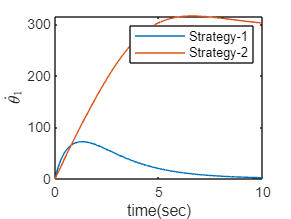

%plot(tspan2,(180/pi)*X_final(:,3))
plot(tspan2,(180/pi)*X_final(:,3),time2,(180/pi)*x_ode2(:,3))
ylabel('$\dot{\theta}_1$', 'Interpreter', 'latex');
xlabel("time(sec)")
legend(["Strategy-1","Strategy-2"])

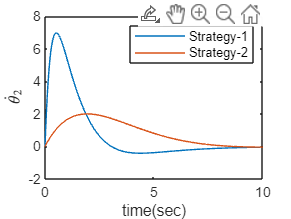

%plot(tspan2,(180/pi)*X_final(:,4))
plot(tspan2,(180/pi)*X_final(:,4),time2,(180/pi)*x_ode2(:,4))
ylabel('$\dot{\theta}_2$', 'Interpreter', 'latex');
xlabel("time(sec)")
legend(["Strategy-1","Strategy-2"])

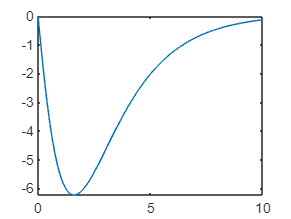

plot(tspan2,(180/pi)*X_final(:,5))

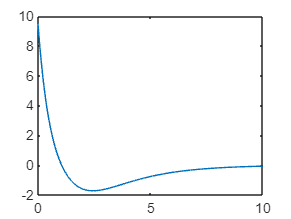

plot(Tau_t(2:size(Tau_t,1),1),Tau_t(2:size(Tau_t,1),2))

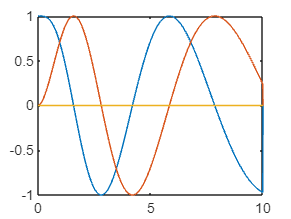

plot(tspan2,PT1(:,1),tspan2,PT1(:,2),tspan2,PT1(:,3));

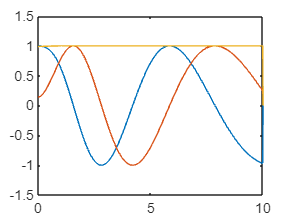

plot(tspan2,PT2(:,1),tspan2,PT2(:,2),tspan2,PT2(:,3));

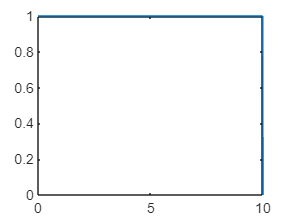

L2 = sqrt(((PT2(:,1)-PT1(:,1)).^2)+((PT2(:,2)-PT1(:,2)).^2)+((PT2(:,3)-PT1(:,3)).^2));
L1 = sqrt(((PT1(:,1)).^2)+((PT1(:,2)).^2)+((PT1(:,3)).^2));
plot(tspan2,L2)

function dxdt = Spatial2RintegratingFBL(time,x)
    %With Feedback Linearization
    
    global K_gain;
    global K_gain_fb;
    global static_force;
    global I_fn h_fn del_fn gam_fn;
    global Tau_t;

%     x(1) = rem(x(1),(2*pi));
%     x(2) = rem(x(2),(2*pi));
    n1 = floor(x(1)/(2*pi));
    n2 = floor(x(2)/(2*pi));
    x(1) = x(1) - (n1*2*pi);
    x(2) = x(2) - (n2*2*pi);
    K_int = 7;
    states = [x(1);x(3);x(2) - pi;x(4)];
    %states = [x(1)- (n1*2*pi);x(3);x(2)- (n2*2*pi)- pi;x(4)];
    eta_2 = (states(2)*cos(states(3))) - (2.5*states(4));
    norm_states = [states(3);states(4);states(1);eta_2];
    I_ode = I_fn(states');
    h_ode = h_fn(time,states');
    del = del_fn(states');
    gam = gam_fn(states');    
    tau = (1/gam)*((-K_gain_fb*norm_states) - del);
    %tau = (-K_gain*states);         %To remove feedback linearization
    %tau = 0;    %Free fall
    F_ext = [tau+static_force+(-K_int*x(5));0];

    if(rem(time,0.01)==0)
        Tau_t = [Tau_t;[time,tau]];
    end

    dxdt(1:2) = x(3:4);
    dxdt(3:4) = I_ode\(F_ext-h_ode);
    dxdt(5) = (x(2) - pi);   %Integral part
    dxdt = transpose(dxdt);

end
%%

function cross2 = vec_cross(a)

    cross2 = [0 -a(3,1) a(2,1);a(3,1) 0 -a(1,1);-a(2,1) a(1,1) 0];

end

%%
function liebrack = LieBracket(f1,f2,y)

    liebrack = simplify((diff_vector(f2,y)*f1) - (diff_vector(f1,y)*f2));
end
%%

function vecdiff = diff_vector(f,y)

    vecdiff_t = symmatrix2sym(symmatrix(zeros(size(y,1),size(f,1))));
    for i = 1:size(y,1)
        vecdiff_t(i,:) = diff(f,y(i,1));
    end

    vecdiff = simplify(vecdiff_t');
end
%%

%Ackermann function
function K = Ackermann(Ac,Bc,poles)

n = size(Ac,1);
m = size(Bc,2);
In = eye(n);
del_A = eye(n);
%Forming characteristic equation
for i=1:n
    del_A = del_A*(Ac-(poles(i)*In));
end
const = zeros(1,n);
const(1,n) = 1;

%Forming controllability matrix
iter = Ac*Bc;
    con = [Bc iter];
    for i = 1:n-2
        iter = Ac*iter;
        con = [con iter];
    end
K = const*(con\del_A);      % For SISO K = [0 0 ...1]*inv(con)*A_desired
end
%%
